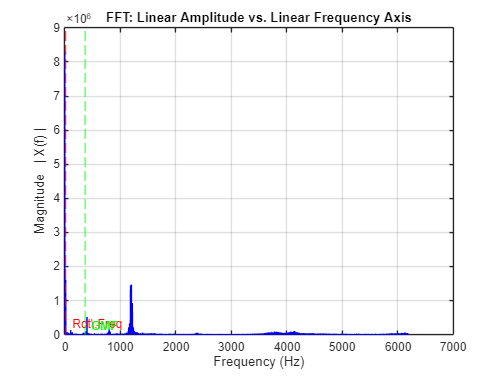

% plotFFTVariants_WithMarkers.m
% This script computes four different FFT-based plots for a given signal x,
% and overlays vertical lines at the rotational frequency (rot_freq) and
% the gear-mesh frequency (gmf) on each plot.
%
% Prerequisites (define these in the Workspace or before running):
%   x         – your time-domain signal (vector)
%   Fs        – sampling frequency in Hz (scalar)
%   rpm       – rotational speed in RPM (scalar)
%   gearteeth – number of teeth on the gear (scalar, used to compute GMF)
%
% Example Workspace setup:
%   rpm       = 1800;        % e.g. 1800 RPM
%   gearteeth = 20;          % e.g. 20 teeth
%   rot_freq  = rpm / 60;    % rotational frequency in Hz
%   gmf       = gearteeth * rot_freq;  % gear-mesh frequency in Hz

% --- Fetch and prepare the signal (unchanged) ---
data = fetch(conn, ...
    "SELECT s.folder, s.filename " + ...
    "FROM siza_csv_files s " + ...
    "JOIN files f ON s.original_file_id = f.id " + ...
    "WHERE f.torque = 200");

i = 1;
signal_path = fullfile(data.folder{i}, data.filename{i});
signal_data = readtable(signal_path);
x = signal_data{:,1};

% --- User‐defined parameters (edit these as needed) ---
Fs        = 12356.19;   % Sampling frequency [Hz]
rpm       = 1000;       % Rotational speed [RPM]
gearteeth = 22;         % Number of teeth on the gear

% Compute frequencies of interest:
rot_freq = rpm / 60;                % Rotational frequency in Hz
gmf      = gearteeth * rot_freq;    % Gear-mesh frequency in Hz

% --- Compute FFT and frequency axis (unchanged) ---
N = length(x);
X = fft(x);
f = (0:N-1) * (Fs / N);
half = 1 : floor(N/2);

% --- 1. Linear‐amplitude plot vs. linear‐frequency axis ---
figure;
plot(f(half), abs(X(half)), 'b');
hold on;
% Overlay vertical lines:
xline(rot_freq, 'r--', 'LineWidth', 1, 'Label', 'Rot\,Freq', 'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom');
xline(gmf,      'g--', 'LineWidth', 1, 'Label', 'GMF',       'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom');
hold off;
xlabel('Frequency (Hz)');
ylabel('Magnitude \midX(f)\mid');
title('FFT: Linear Amplitude vs. Linear Frequency Axis');
grid on;

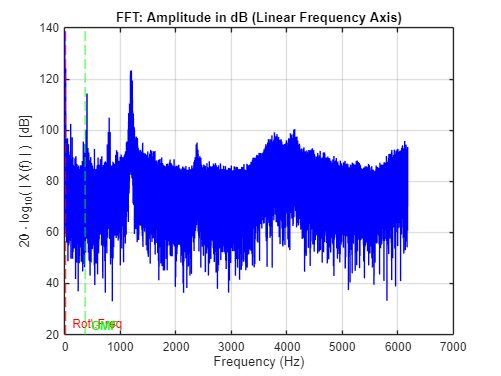


% --- 2. Amplitude in dB vs. linear‐frequency axis ---
figure;
plot(f(half), 20*log10(abs(X(half))), 'b');
hold on;
% Overlay vertical lines:
xline(rot_freq, 'r--', 'LineWidth', 1, 'Label', 'Rot\,Freq', 'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom');
xline(gmf,      'g--', 'LineWidth', 1, 'Label', 'GMF',       'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom');
hold off;
xlabel('Frequency (Hz)');
ylabel('20\cdotlog_{10}(\midX(f)\mid) [dB]');
title('FFT: Amplitude in dB (Linear Frequency Axis)');
grid on;

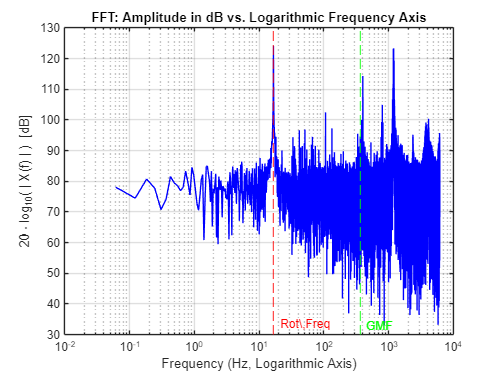


% --- 3. Amplitude in dB vs. logarithmic‐frequency axis ---
pos = half(2:end);  % skip DC for log-scale
figure;
semilogx(f(pos), 20*log10(abs(X(pos))), 'b');
hold on;
% Overlay vertical lines (only plot if > 0 Hz)
if rot_freq > 0
    xline(rot_freq, 'r--', 'LineWidth', 1, 'Label', 'Rot\,Freq', 'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom');
end
if gmf > 0
    xline(gmf, 'g--', 'LineWidth', 1, 'Label', 'GMF', 'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom');
end
hold off;
xlabel('Frequency (Hz, Logarithmic Axis)');
ylabel('20\cdotlog_{10}(\midX(f)\mid) [dB]');
title('FFT: Amplitude in dB vs. Logarithmic Frequency Axis');
grid on;

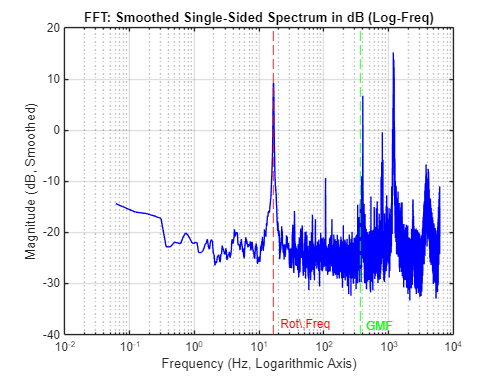


% --- 4. Smoothed, single‐sided spectrum in dB vs. log‐frequency axis ---
% Compute single-sided spectrum:
P2 = abs(X / N);
P1 = P2(1:floor(N/2)+1);
P1(2:end-1) = 2 * P1(2:end-1);
f1 = Fs * (0:(N/2)) / N;
P1_dB = 20 * log10(P1);
P1_dB_smooth = movmean(P1_dB, 10);

figure;
semilogx(f1(2:end), P1_dB_smooth(2:end), 'b');  % skip DC for log-scale
hold on;
% Overlay vertical lines:
if rot_freq > 0
    xline(rot_freq, 'r--', 'LineWidth', 1, 'Label', 'Rot\,Freq', 'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom');
end
if gmf > 0
    xline(gmf, 'g--', 'LineWidth', 1, 'Label', 'GMF', 'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom');
end
hold off;
grid on;
xlabel('Frequency (Hz, Logarithmic Axis)');
ylabel('Magnitude (dB, Smoothed)');
title('FFT: Smoothed Single-Sided Spectrum in dB (Log-Freq)');


% --- End of script ---
